close all;


This script reads a single CSV measurement and determines the decibel at the peak and the Q factor. 

For reading multiple measurments, see V2.

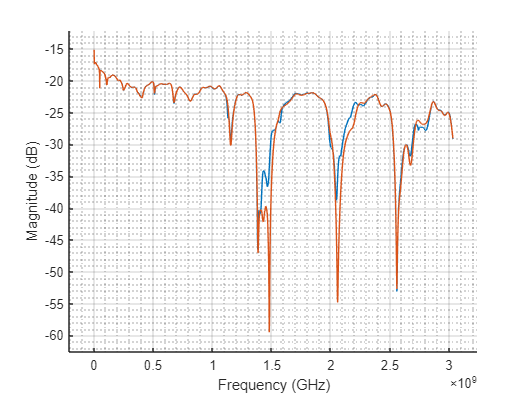

%locates the cvs file to pull the data from
[file,path] = uigetfile;
filepath = append(path,file);
data = csvread(filepath, 3, 0)';  %the arguments are at which point the data starts
data(3,:) = [];
dtitle = append(extractBetween(path,4,7)," - ",file);

[file,path] = uigetfile;
filepath = append(path,file);
data2 = csvread(filepath, 3, 0)';  %the arguments are at which point the data starts
data2(3,:) = [];
dtitle = append(extractBetween(path,4,7)," - ",file);

%finds the extremes of the dataset to adjust the graph boundaries
ymax = max(data(2,:));
ymin = min(data(2,:));
xlim = [data(1,1) data(1,end)];
ylim = [ymin ymax];

figure()
hold on
plot(data(1,:), data(2,:),data2(1,:), data2(2,:));
axis([xlim ylim])
axis padded
grid on
grid minor;
%title(dtitle);
xlabel("Frequency (GHz)");
ylabel("Magnitude (dB)");



%readjust range to cut out the 1.4GHz peak
trim = find(data(1,:)>1000000000)-1;
trim = trim(1,1);
ymin = min(data(2,1:trim));

fmin = islocalmin(data(2,1:trim),'MinProminence',7); %finds the index of the peak
xpeak = find(fmin);    %connects that index to the frequency value
precsion = 15;

if xpeak > 0
    frez = data(1,xpeak);              
    fprintf("Resonance at %.2f MHz at %.1f dB.\n",frez/1000000,ymin)
    peakrange= data(1:2,xpeak-precsion:xpeak+precsion);
    

    %interpolate the peak to calculate peak -3dB
    steps = (peakrange(1,end)-peakrange(1,1))/200;
    finescale = peakrange(1,1):steps:peakrange(1,end); %create finer scale with same boundaries
    
    interpol = interp1(peakrange(1,:),peakrange(2,:),finescale,'cubic');
    plot(peakrange(1,:),peakrange(2,:),'o',finescale,interpol,':.');

    interdata = [finescale;interpol]; %parse vectors together

    %determine full width at half maximum
    halfmax = ymin+3;
    halfy = find(interdata(2,:) < halfmax);      %find the range where the data is below the values

    fullwidth = abs(interdata(1,halfy(1)) - interdata(1,halfy(end)));    %calcutate the frequency width
    
    %calculate the Q factor
    Q = frez/fullwidth;
    fprintf("Q factor is %.2f \n",Q)

else
    fprintf("No peak found within parameters")
end

No peak found within parameters